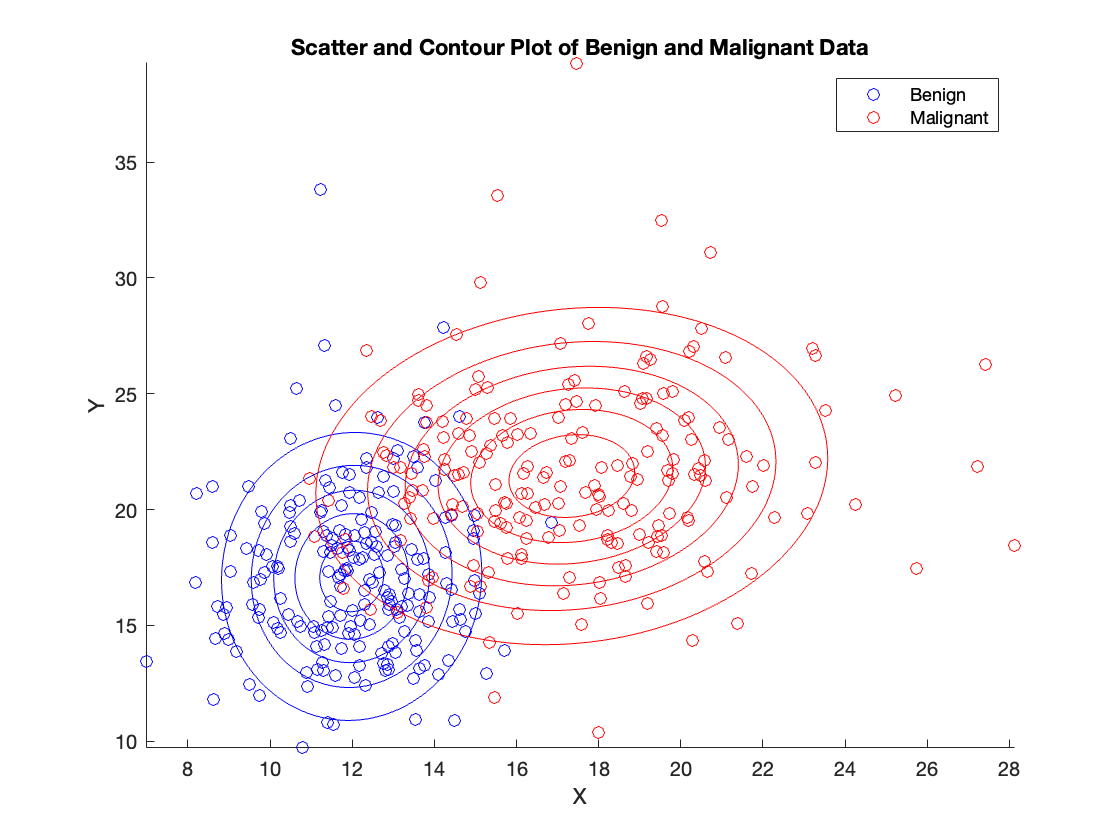

% (a)

% Load .csv data into matrix variables
benign = readmatrix("benignfull.csv");
malignant = readmatrix("malignantfull.csv");

% Create scatter plot (i),(ii)
figure;
hold on;
scatter(benign(:, 1), benign(:, 2), 'b');
scatter(malignant(:, 1), malignant(:, 2), 'r');
xlabel('X');
ylabel('Y');

% Create contour plot (iii),(iv)
hold on; 
gaussiancontour(benign(:, 1), benign(:, 2), 'b');
gaussiancontour(malignant(:, 1), malignant(:, 2), 'r');

legend('Benign', 'Malignant');
title('Scatter and Contour Plot of Benign and Malignant Data');


% (b)

bening_corrcoef = corrcoef(benign);

% Find indices of columns with highest correlation coefficient
bening_corrcoef(logical(eye(size(bening_corrcoef)))) = -Inf;

% Find the indices of the two columns with the highest correlation coefficient
[~, max_idx] = max(bening_corrcoef(:));
[row_idx, col_idx] = ind2sub(size(bening_corrcoef), max_idx);

% Display the column indices and correlation coefficient
fprintf(['The two columns with correlation coefficient ' ...
    'closest to 1 are columns %d and %d with correlation ' ...
    'coefficient %.4f.\n'], row_idx, col_idx, ...
    bening_corrcoef(row_idx, col_idx));

The two columns with correlation coefficient closest to 1 are columns 3 and 1 with correlation coefficient 0.9963.


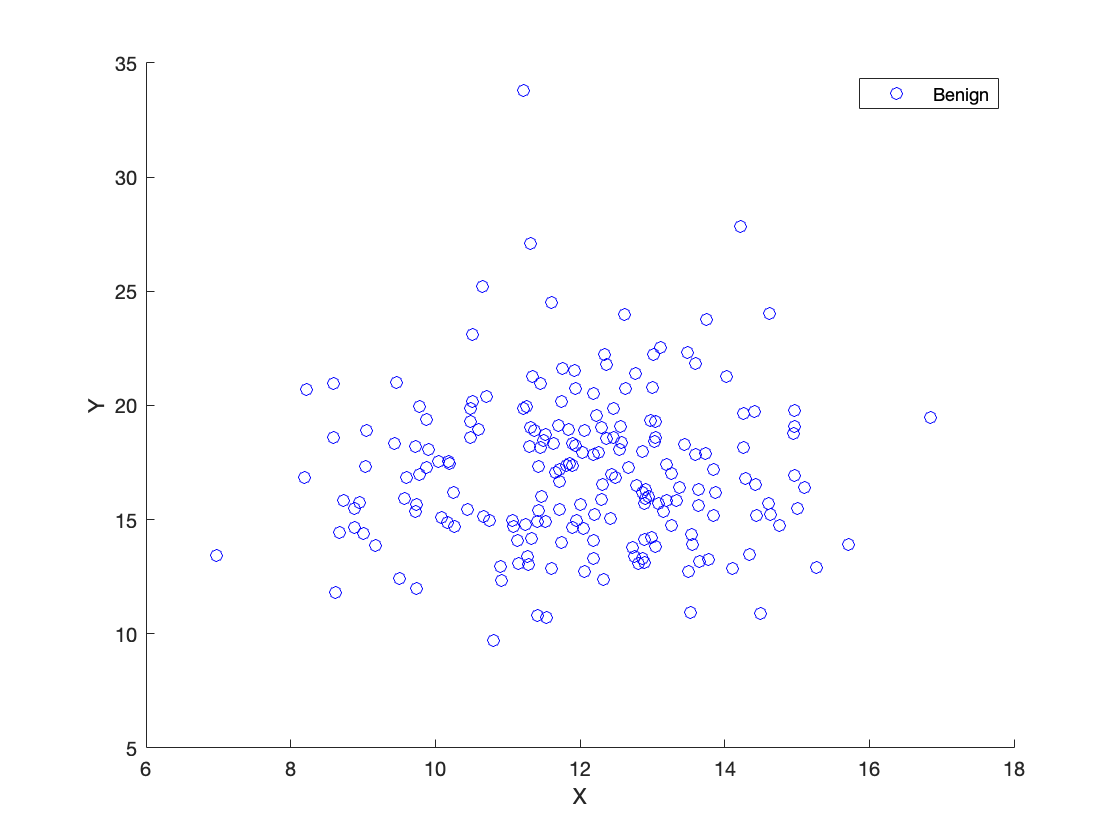


figure;
scatter(benign(:, 1), benign(:, 2), 'b');
xlabel('X');
ylabel('Y');
legend('Benign');


fprintf(['If their correlation coefficient is close' ...
    'to one, then we know that in general, as one variable' ...
    'grows, the other tends to also grow.'])

If their correlation coefficient is closeto one, then we know that in general, as one variablegrows, the other tends to also grow.


% Find the indices of the two columns with the lowest correlation coefficient
[~, min_abs_idx] = min(abs(bening_corrcoef(:)));
[row_idx, col_idx] = ind2sub(size(bening_corrcoef), min_abs_idx);

fprintf(['The two columns with correlation coefficient ' ...
    'closest to 0 are columns %d and %d with correlation ' ...
    'coefficient %.4f.\n'], row_idx, col_idx, ...
    bening_corrcoef(row_idx, col_idx));

The two columns with correlation coefficient closest to 0 are columns 10 and 2 with correlation coefficient -0.0150.


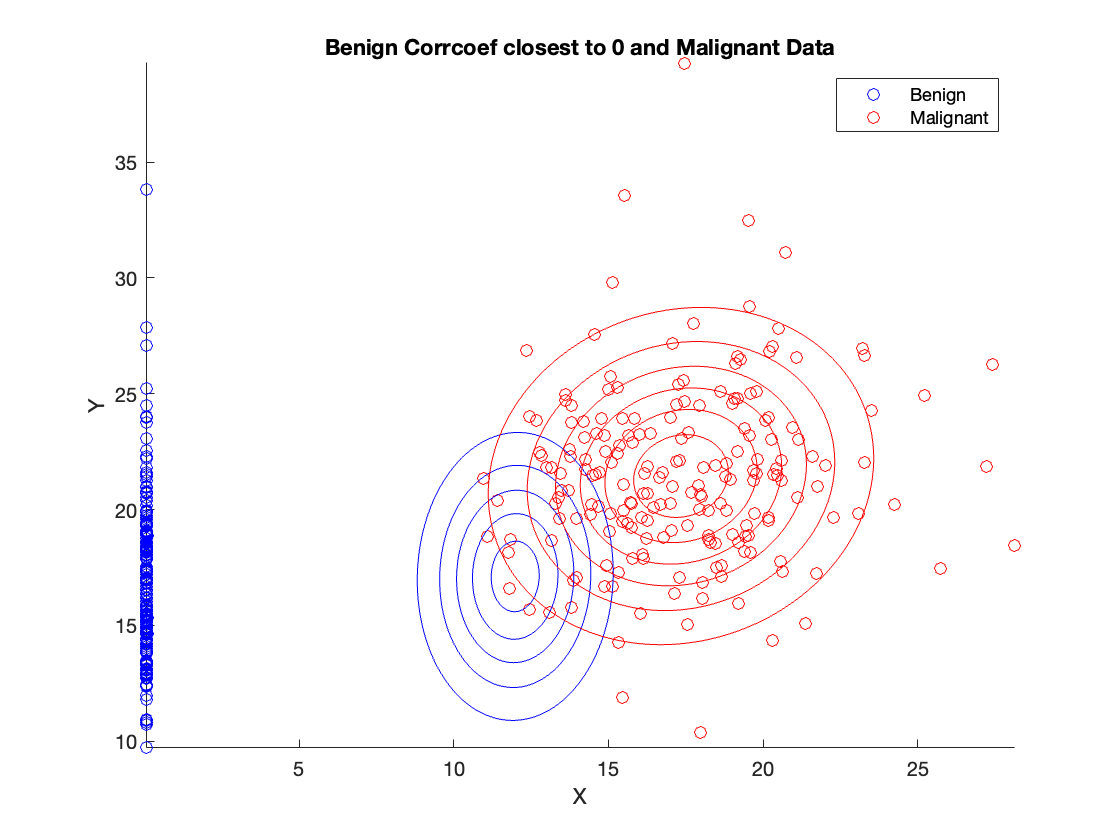


% Plot the columns with correlation coef closest to 0
figure; 
hold on; 

b_min_x = benign(:, row_idx);
b_min_y = benign(:, col_idx);

scatter(b_min_x,b_min_y,'b');
scatter(malignant(:, 1), malignant(:, 2), 'r');
gaussiancontour(benign(:, 1), benign(:, 2), 'b');
gaussiancontour(malignant(:, 1), malignant(:, 2), 'r');
xlabel('X');
ylabel('Y');
legend('Benign','Malignant');
title('Benign Corrcoef closest to 0 and Malignant Data');


fprintf(['We see the Y axis with values stacking up' ...
    'because this is what is expected when values have' ...
    'a very low correlation coefficient.']);

We see the Y axis with values stacking upbecause this is what is expected when values havea very low correlation coefficient.

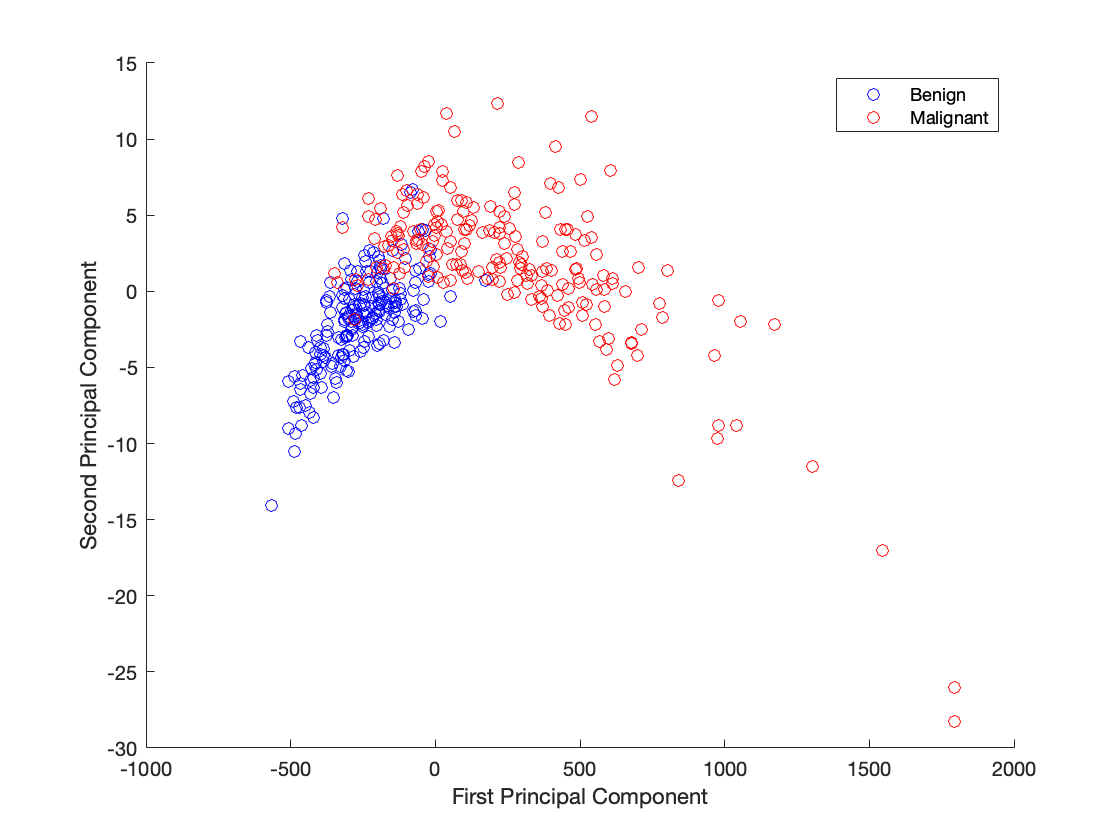


% (c)

% Call visualize2d and plot
% call the visualize2d function to get the 2D representations of the datasets
[dataset0_2d, dataset1_2d] = visualize2d(benign, malignant);

% plot the datasets as a scatter plot
figure;
scatter(dataset0_2d(:,1), dataset0_2d(:,2), 'b');
hold on;
scatter(dataset1_2d(:,1), dataset1_2d(:,2), 'r');
xlabel('First Principal Component');
ylabel('Second Principal Component');
legend('Benign', 'Malignant');

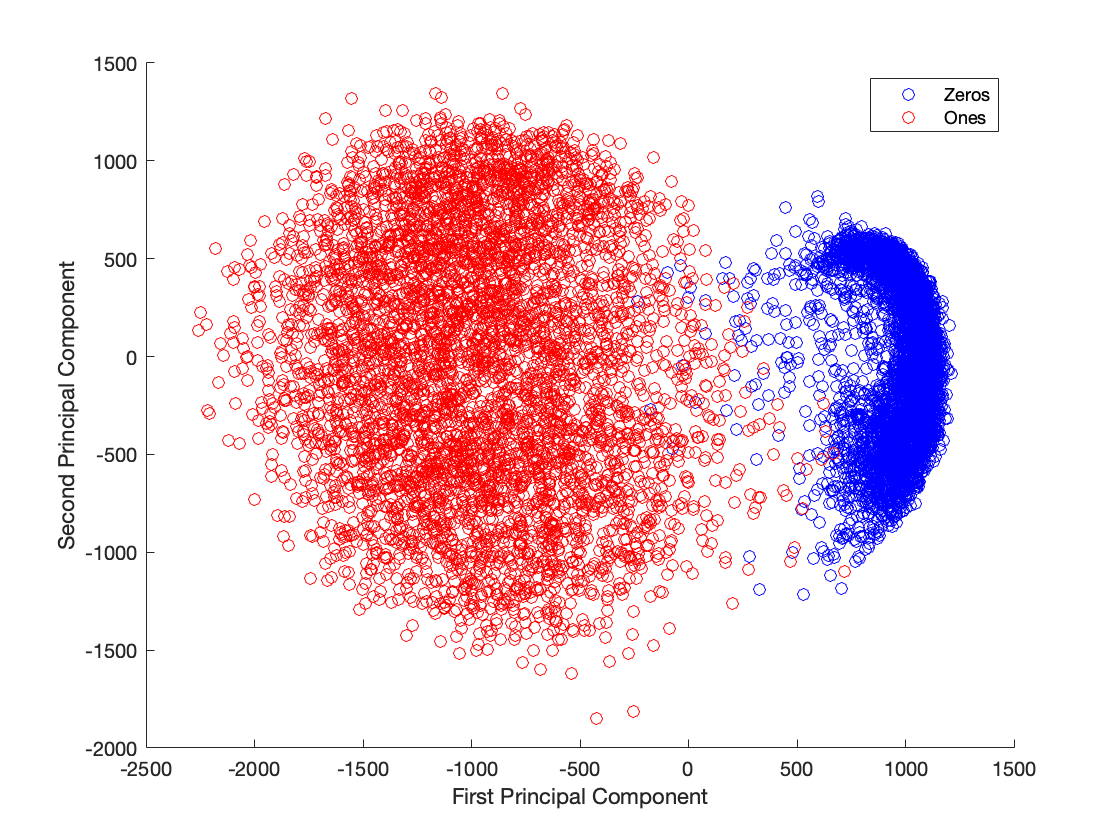


% (d) 
ones = readmatrix('MNISTones.csv');
zeros = readmatrix('MNISTzeros.csv');
[dataset0_2d, dataset1_2d] = visualize2d(ones,zeros);

figure;
scatter(dataset0_2d(:,1), dataset0_2d(:,2), 'b');
hold on;
scatter(dataset1_2d(:,1), dataset1_2d(:,2), 'r');
xlabel('First Principal Component');
ylabel('Second Principal Component');
legend('Zeros', 'Ones');


fprintf(['This data set looks to be easier to classify than the other data set']);

This data set looks to be easier to classify than the other data set

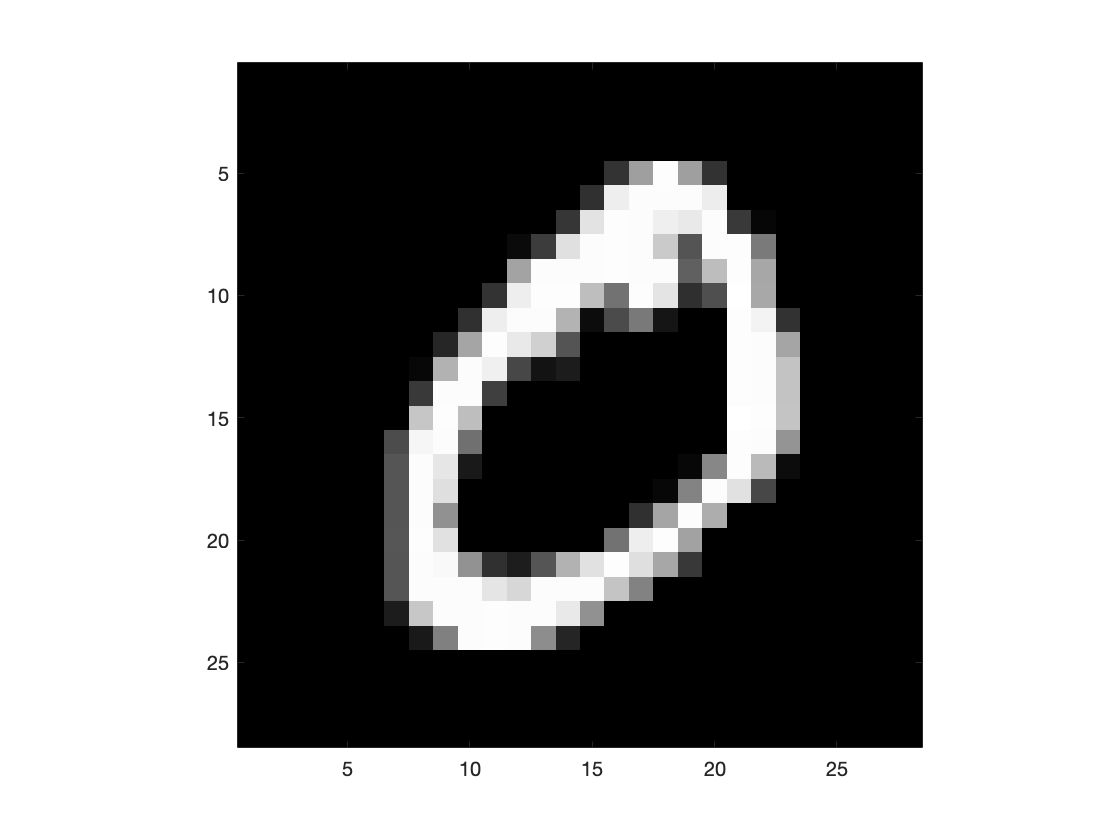


figure;
show_image(zeros, 1); 


% (f)

cats_dogs = read_cats_dogs;